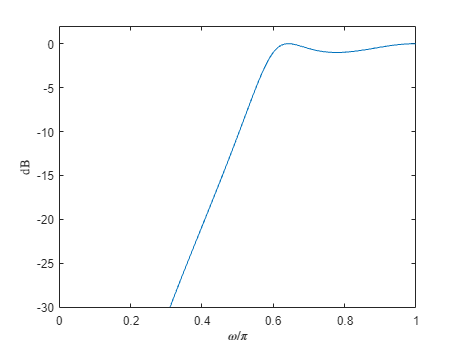

Rp=1;Rs=20;T=0.001;fp=300;fs=200;
wp=2*pi*fp*T;ws=2*pi*fs*T;
wp1=(2/T)*tan(wp/2);ws1=(2/T)*tan(ws/2);
[n,wn]=cheb1ord(wp1,ws1,Rp,Rs,"s");[b,a]=cheby1(n,Rp,wn,'high','s');
[bz,az]=bilinear(b,a,1/T);
[db,mag,pha,grd,w]=freqz_m(bz,az);plot(w/pi,db);axis([0,1,-30,2]);
ylabel('dB',Interpreter='latex')
xlabel('$\omega/\pi$',Interpreter='latex')